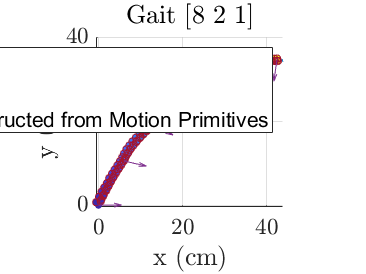

load gait_analysis_MTA3_new.mat
t_n =19;
dim = 1;
figure
all_gaits(t_n).plot

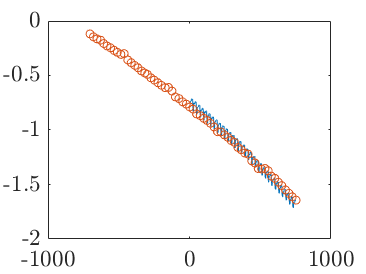


figure
% all_gaits(t_n).keyframes(1):all_gaits(t_n).keyframes(1)+length(data_n)-1, 
data_n = all_gaits(t_n).poses(dim,all_gaits(t_n).keyframes(1):all_gaits(t_n).keyframes(end));
plot(data_n)
hold on

key_keyframes = all_gaits(t_n).keyframes(2:all_gaits(t_n).len_gait:end);
scatter(key_keyframes-all_gaits(t_n).keyframes(1)+1, all_gaits(t_n).poses(dim,key_keyframes)) 

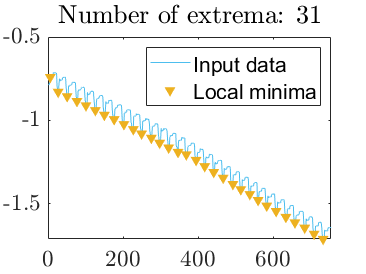

% Find local minima
minIndices = islocalmin(data_n,"MinSeparation",13,"MaxNumExtrema",31);

% Display results
clf
plot(data_n,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local minima
plot(find(minIndices),data_n(minIndices),"v","Color",[237 177 32]/255,...
    "MarkerFaceColor",[237 177 32]/255,"DisplayName","Local minima")
title("Number of extrema: " + nnz(minIndices))
hold off
legend

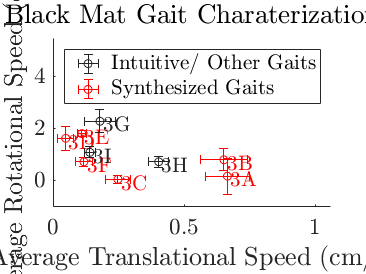



figure
hold on
plot_gait_char(1:2:11,names_bm(1:6),speed_data,1)
plot_gait_char(13:2:17,names_bm(7:9),speed_data,0)
ylim([-1 5.5])
xlim([0 1.06])
title('Black Mat Gait Charaterization', 'FontSize',20)
ax = gca;
legend([ax.Children(4), ax.Children(11)],["Intuitive/ Other Gaits", "Synthesized Gaits"],'Interpreter','latex')

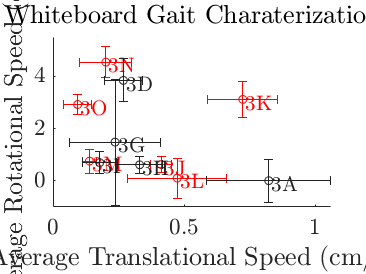


figure
hold on
plot_gait_char(19:24,names_wb(1:6),speed_data,1)
plot_gait_char([25:27,29,31],names_wb(7:11),speed_data,0)
title('Whiteboard Gait Charaterization','FontSize',20)
ylim([-1 5.5])
xlim([0 1.06])

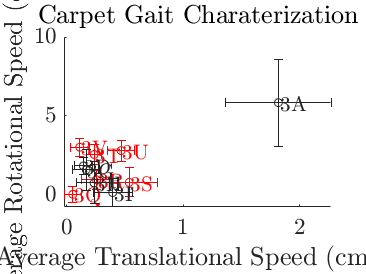


figure
hold on
plot_gait_char(33:38,names_ct(1:6),speed_data,1)
plot_gait_char(39:43,names_ct(7:11),speed_data,0)

title('Carpet Gait Charaterization', 'FontSize',20)

function plot_gait_char(trial_nums, trial_labels, speed_data, is_synth)
if is_synth
    l_color = "red";
else
    l_color = "#242424";
    xlabel('Average Translational Speed (cm/s)')
    ylabel('Average Rotational Speed (deg/s)')
end
x = speed_data(1,trial_nums);
    x_err = speed_data(2,trial_nums);
    y = speed_data(3,trial_nums);
    y_err = speed_data(4,trial_nums);
    
    errorbar(x,y,y_err,y_err,x_err,x_err,"o","Color",l_color); 
for i = 1:length(trial_nums)
    text(x(i)+.01, y(i)-.2, "3"+trial_labels(i),"Color", l_color,'FontSize',16)
end
end
